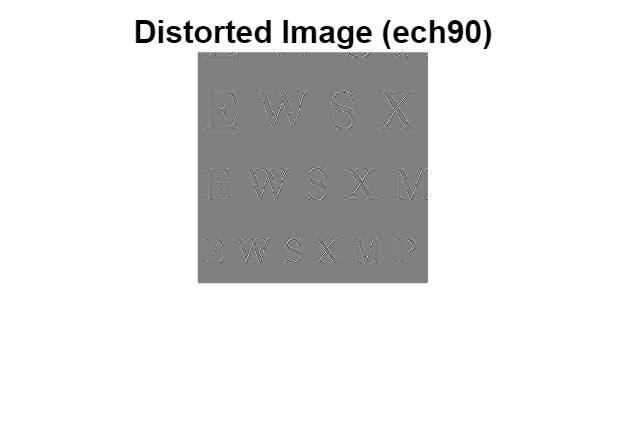

% (b) Apply FIR FILTER-1 in both directions
q = 0.9;
h1 = [1, -q];

% Apply the filter horizontally
ech90_h = filter2(h1, echart);

% Apply the filter vertically
ech90 = filter2(h1', ech90_h);

% Display the distorted image
figure;
imshow(ech90, []);
title('Distorted Image (ech90)');

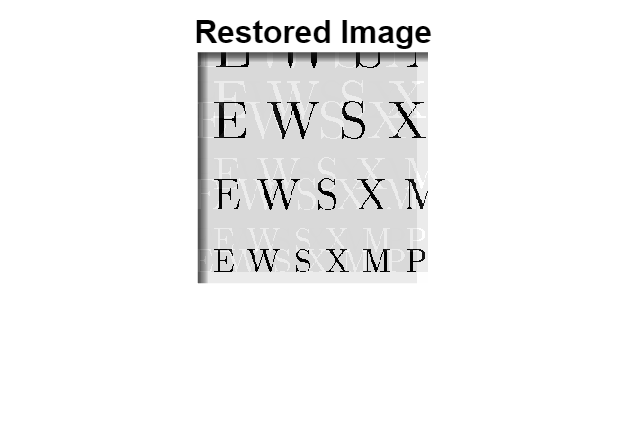


% (c) Deconvolve ech90 with FIR FILTER-2
r = 0.9;
M = 22;
h2 = r .^ (0:M);

% Apply the deconvolution filter horizontally
ech_restored_h = filter2(h2, ech90);

% Apply the deconvolution filter vertically
ech_restored = filter2(h2', ech_restored_h);

% Display the restored image
figure;
imshow(ech_restored, []);
title('Restored Image');

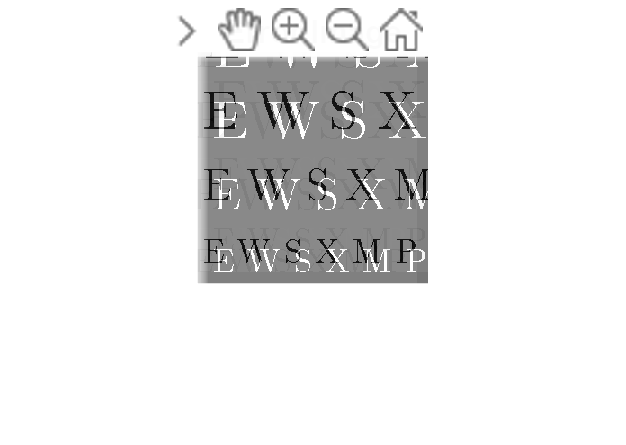


% Evaluate the worst-case error
error_image = echart - ech_restored;
worst_case_error = max(abs(error_image(:)));

% Display the error image
figure;
imshow(error_image, []);
title('Error Image');


% Display the worst-case error
disp(['Worst-Case Error: ', num2str(worst_case_error)]);

Worst-Case Error: 300.201
